# **Read a GMSH model by physical groups**

This example demonstrates how to read a GMSH model by physical groups and convert it to an OpenSeesPy model using the *Gmsh2OPS* class.

This example is based on GMSH Example [t15](https://gmsh.info/doc/texinfo/gmsh.html#t15).

**msh** file can be found in [](../utils/t15.msh).

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

g2o = opsMAT.pre.Gmsh2OPS;

g2o.readGmshFile('utils/t15.msh');

Info:: 5 Physical Names.
Info:: 166 Nodes; MaxNodeTag 166; MinNodeTag 1.
Info:: 571 Elements; MaxEleTag 571; MinEleTag 1.
Info:: Geometry Information >>>
43 Entities: 17 Point; 18 Curves; 7 Surfaces; 1 Volumes.

Info:: Physical Groups Information >>>
3 Physical Groups.
Physical Group names: Boundary, Load, Volume

Info:: Mesh Information >>>
166 Nodes; MaxNodeTag 166; MinNodeTag 1.
567 Elements; MaxEleTag 571; MinEleTag 5.



In the example above, we defined the following physical groups for converting OpenSees elements. Volume 1 is used to generate elements, while the boundary consists of the bottom 1 surface, 4 lines, and 4 points!

- gmsh.model.addPhysicalGroup(dim=0, tags=[1, 2, 9, 13], tag=1, name=”Boundary”) # points

- gmsh.model.addPhysicalGroup(dim=1, tags=[1, 8, 13, 17], tag=2, name=”Boundary”) # lines

- gmsh.model.addPhysicalGroup(dim=2, tags=[18], tag=3, name=”Boundary”) # surface

- gmsh.model.addPhysicalGroup(dim=2, tags=[27], tag=4, name=”Load”) # surface load

- gmsh.model.addPhysicalGroup(dim=3, tags=[1], tag=4, name=”Volume”) # volume

physicalGroups = g2o.getPhysicalGroups();
disp(physicalGroups.keys());

    {'Boundary'}    {'Load'}    {'Volume'}



ops.wipe()
% Initialize a basic 3D model with 3 degrees of freedom per node
ops.model("basic", "-ndm", 3, "-ndf", 3)

% Define an elastic isotropic material
% Material ID: 1
% Elastic modulus: 3e7
% Poisson's ratio: 0.2
% Density: 2.55
matTag = 1;
ops.nDMaterial("ElasticIsotropic", matTag, 3e7, 0.2, 2.55)

% Create OpenSeesPy node commands based on all nodes
g2o.createNodeCmds();  

% Create OpenSeesPy element commands for specific entities
% FourNodeTetrahedron elements
%
eleTags = g2o.createElementCmds(...
    "FourNodeTetrahedron", ...  % OpenSeesPy element type
    OpsEleArgs={matTag}, ...  % Additional arguments for the element (e.g., mat tag)
    PhysicalGroupNames="Volume");

% fixed nodes
fix_node_tags = g2o.getNodeTags(PhysicalGroupNames="Boundary");
for i = 1: numel(fix_node_tags)
    ops.fix(fix_node_tags(i), 1, 1, 1);
end

% If there are too many geometries on the boundary, you can iterate through and extract all lines and points on a geometry using the following commands:
boundary_dim_tags = g2o.getBoundaryDimTags(DimEntityTags=[2, 18], IncludeSelf=true);
disp(boundary_dim_tags);

     0     1
     0     2
     0     9
     0    13
     1     1
     1     8
     1    13
     1    17
     2    18



disp(physicalGroups("Boundary"));

     0     1
     0     2
     0     9
     0    13
     1     1
     1     8
     1    13
     1    17
     2    18



[OpenSeesMatlab] Model summary
  Nodes: 166
  Solid elements: 473


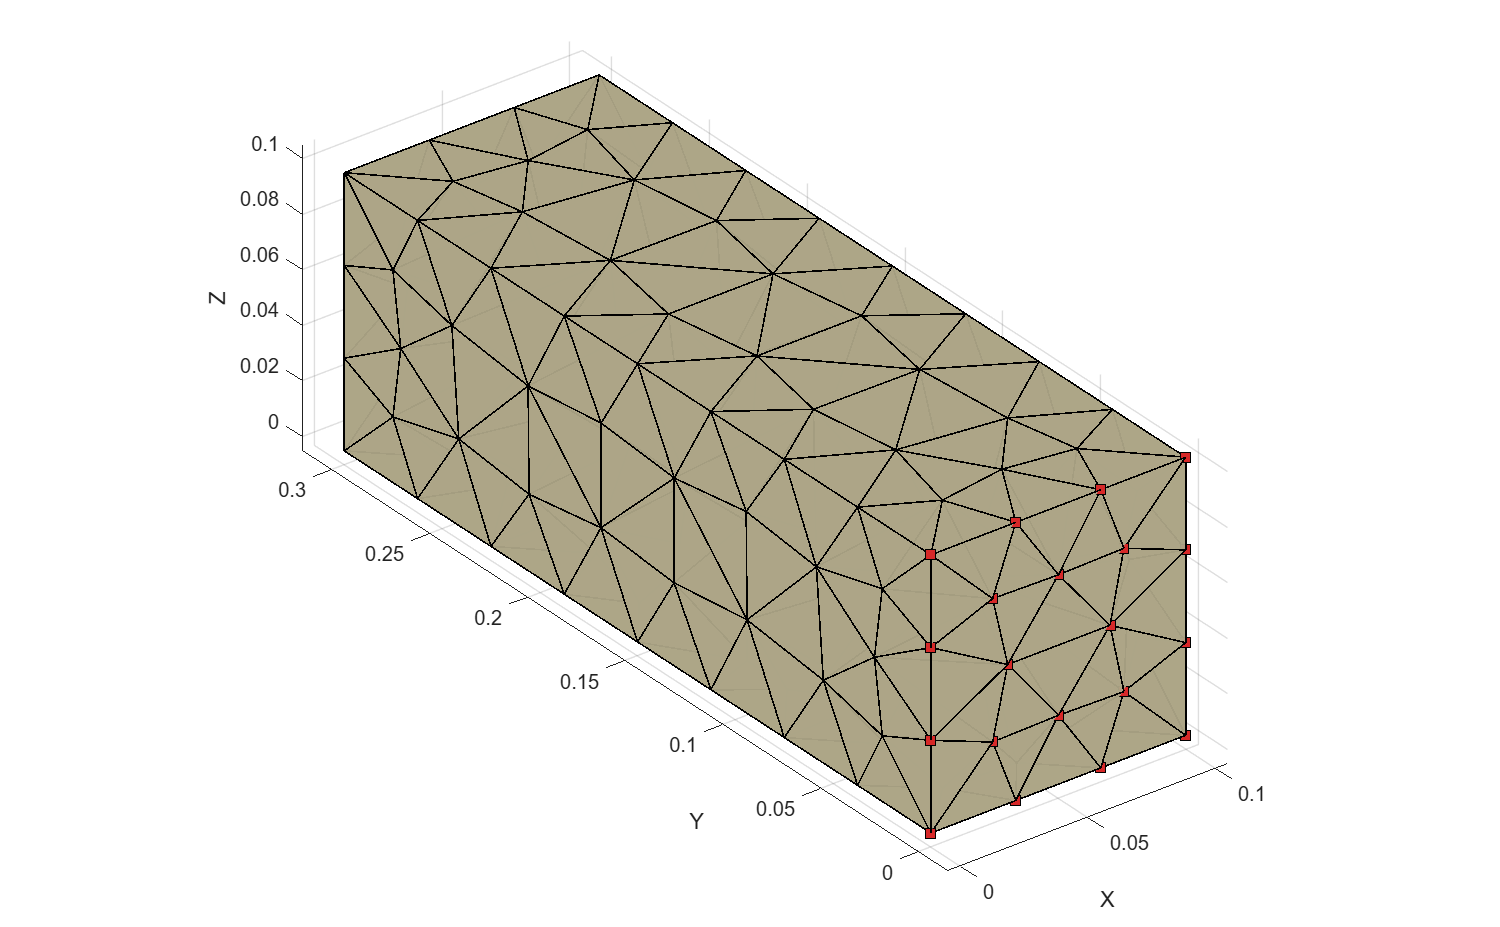

opsMAT.vis.plotModel();

Eigen analysis:

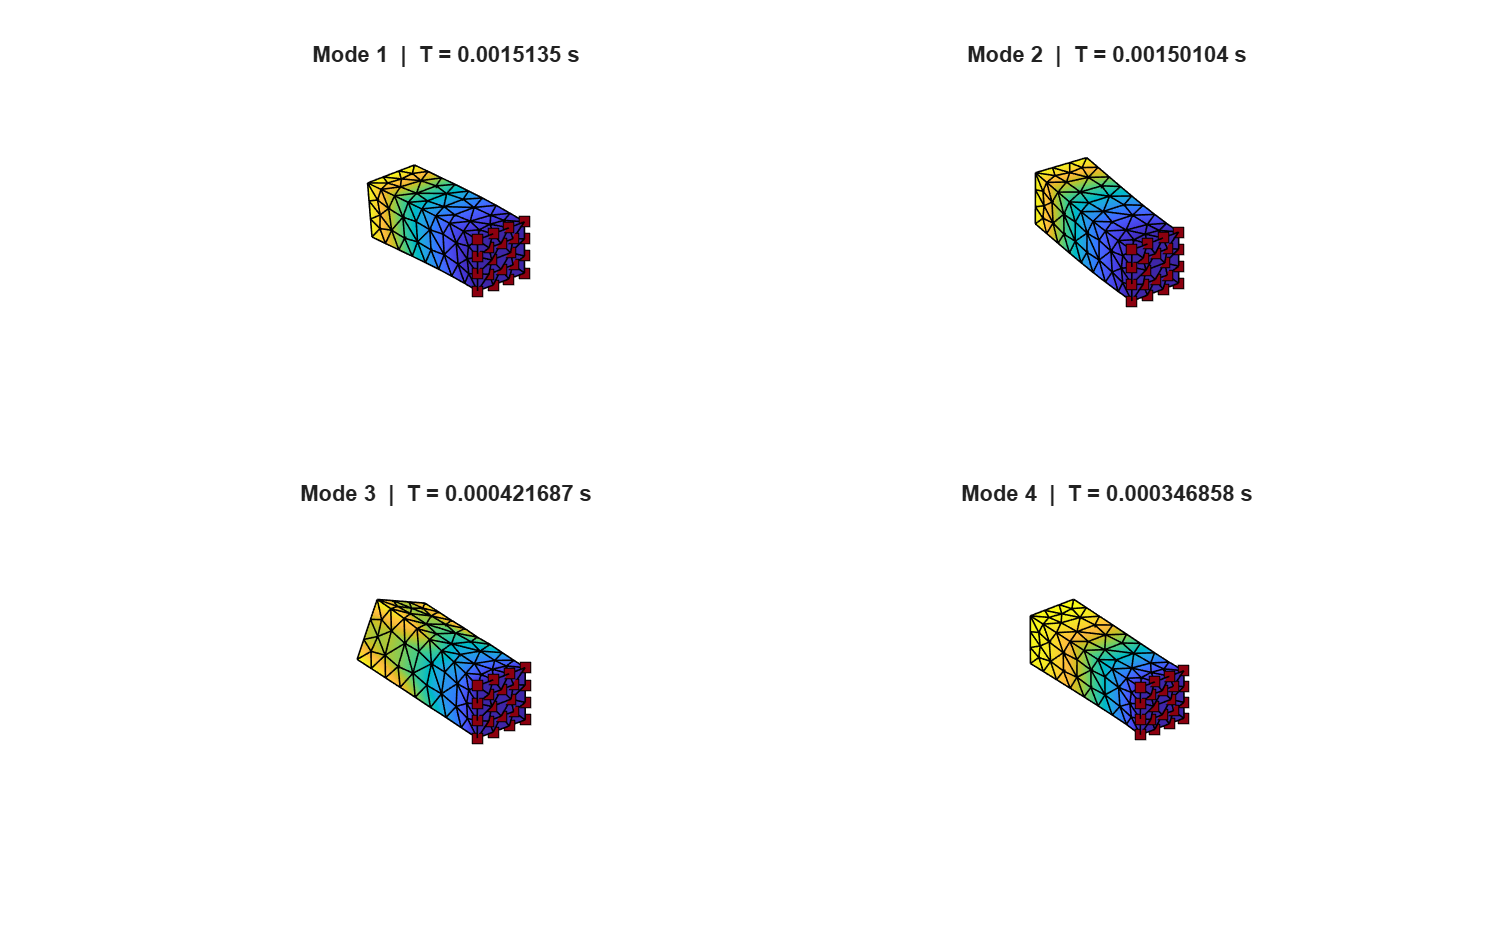

tag = 1;
opsMAT.post.saveEigenData(tag, 10, solver='-genBandArpack');
eigenData = opsMAT.post.getEigenData(odbTag=tag);

opts = opsMAT.vis.defaultPlotEigenOptions;
opts.color.useColormap = true;
% opts.color.colormap = jet(256);
modeTags = 1:4;
cmps = "parula";
for i = 1:4
    subplot(2,2,i)
    ax = gca();
    opsMAT.vis.plotEigen(modeTags(i), eigenData, opts=opts, ax=ax);
    axis off;
    colormap(ax, cmps);
end

We can apply the load by extracting the elements belonging to surface with tag 27: First, we convert the element to which the surface load is applied to [SurfaceLoad Element](https://opensees.berkeley.edu/wiki/index.php?title=SurfaceLoad_Element), and then we can apply the surface load to it:

pressure = -1;
load_ele_tags = g2o.createElementCmds(...
    "TriSurfaceLoad", ...  % OpenSeesPy element type
    OpsEleArgs={pressure}, ...  % Additional arguments for the element
    PhysicalGroupNames="Load");
load_ele_tags = num2cell(load_ele_tags);

ops.timeSeries("Linear", 1)
ops.pattern("Plain", 1, 1)
ops.eleLoad("-ele", load_ele_tags{:}, "-type", "-surfaceLoad")

ops.constraints("Transformation")
ops.numberer("RCM")
ops.system("BandGeneral")
ops.test("NormDispIncr", 1.0e-12, 6, 2)
ops.algorithm("Linear")
ops.integrator("LoadControl", 0.1)
ops.analysis("Static")
ops.analyze(10)